clear

addpath("matlab_functions\")

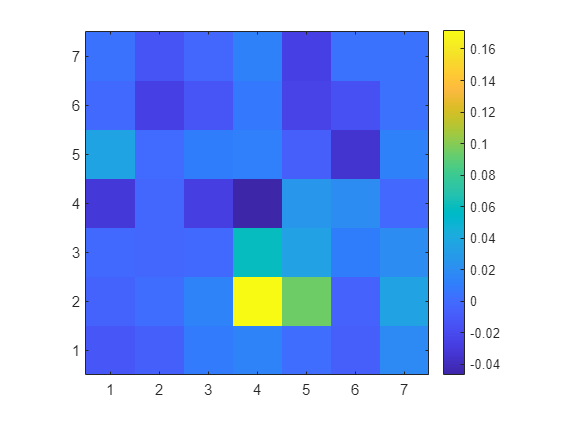

N = 20; % image width

h = 5;
kernel = fspecial('average',h);

idx = reshape(1:N^2, N,N);

A = sparse(N^2);
offset = -ceil(h/2);
row = 1;
for y = 1:3:N
for x = 1:3:N
    for p = 1:h
    for q = 1:h
        i = x + p + offset;
        i = min(max(i,1), N);
        j = y + q + offset;
        j = min(max(j,1), N);
        A(row, idx(i,j)) = kernel(p,q);
    end
    end
    row = row + 1;
end
end
clear h kernel idx offset x y p q i j row

x = zeros(N^2,1);
x(70:71) = 1;
x(90:91) = 1;

y = A * x;
y = y + normrnd(0, 0.02, size(y));

figure
imagesc(reshape(y,sqrt(length(y)),[]).')
colorbar
axis square xy

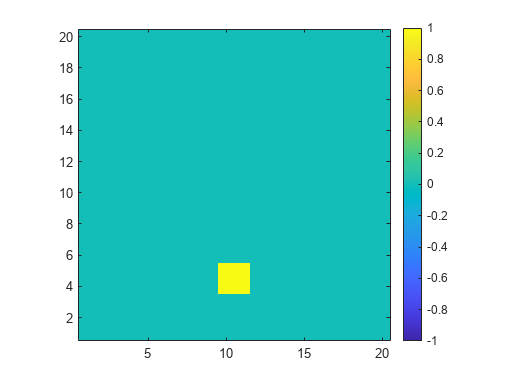


figure
imagesc(reshape(x,N,N).', [-max(x) max(x)])
colorbar
axis square xy

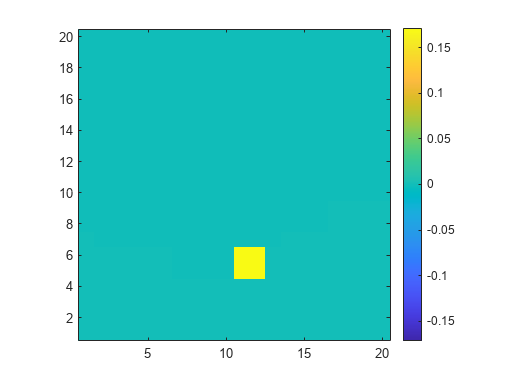


reg{1}.lambda = 1e-2;
reg{1}.L = speye(N^2);
x1 = L1Regularize(A,y, reg, 1e-2);
clear reg

figure
imagesc(reshape(x1,N,N).', [-max(x1) max(x1)])
colorbar
axis square xy

[r1,r2,r3] = ndgrid(1:N,1:N,1);
element_centers = [reshape(r1,1,[]); reshape(r2,1,[]); reshape(r3,1,[])];
b = 2;
Psi = ElementsOperation('BlockGroup', element_centers, b,b,1);

x2 = BlockSBL(A,y, 'BlockLength',b^2, 'StructureAwareMatrix',Psi, ...
    'ShareCorrelationMatrix',false, 'MaxIterations',1000, 'Tolerance',1e-4);

Terminated after reaching maximum iterations


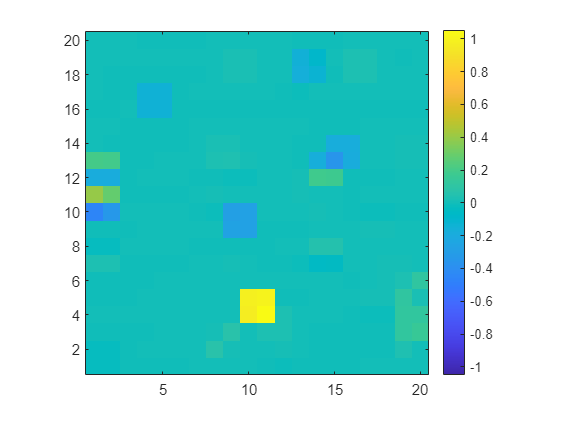

clear r1 r2 r3 element_centers b Psi

figure
imagesc(reshape(x2,N,N).', [-max(x2) max(x2)])
colorbar
axis square xy